%a
[time_pos, sq_wave, B_unnorm] = generate_data;

plot(time_pos,sq_wave)
title("Square Wave Signal")
xlabel('Time')
ylabel('Wave')

%b
%I would use the normalizing function then dot the vectors. If they equal
%zero, the vectors are orthogonal. I would have this function execute
%within a nested for loop so that every vector is compared with every other
%vector

subplot(2,4,1)
plot(time_pos,B_unnorm(1,:))
subplot(2,4,2)
plot(time_pos,B_unnorm(2,:))
subplot(2,4,3)
plot(time_pos,B_unnorm(3,:))
subplot(2,4,4)
plot(time_pos,B_unnorm(4,:))
subplot(2,4,5)
plot(time_pos,B_unnorm(5,:))
subplot(2,4,6)
plot(time_pos,B_unnorm(6,:))
subplot(2,4,7)
plot(time_pos,B_unnorm(30,:))

%c)

%project the square wave signal onto the normalized basis vectors using l2
%projection and compute coeef efficient
%arrange the square wave using the first 1,2,3,4,5,6,30 vectors

%init
B = B_unnorm(1,:);
sq_wave
size(sq_wave)
B
vec_proj = dot(sq_wave,B)/dot(B,B).*B;
coeffs = transpose(vec_proj)
vec_proj(1)
vec_proj(2)
size(vec_proj)
size(coeffs)
coeffs(1)
coeffs(2)
norm = [dot(vec_proj,vec_proj)]
norm
for vector = 2:30
    B = B_unnorm(vector,:);
    vec_proj = transpose(dot(sq_wave,B)/dot(B,B)*B);
    n = dot(vec_proj,vec_proj);
    if n > norm(1)
        temp_norm = [n norm(1:end)];
        norm = temp_norm;
        temp_coeffs = [vec_proj , coeffs];
        coeffs = temp_coeffs;
    elseif n < norm(end)
        temp_norm = [norm(1:end) n];
        norm = temp_norm;
        temp_coeffs = [coeffs , vec_proj];
        coeffs = temp_coeffs;
    else
        i = 1
        length(norm)
        size(norm)
        norm
        n
        norm
        while ((i < length(norm)) & (n < norm(i)))
            i = i + 1;
        end
        temp_n = [norm(1:(i-1)) n norm(i:end)];
        norm = temp_norm;
        size(coeffs)
        size(vec_proj)
        temp_coeffs = [coeffs(:, 1:(i-1)) , vec_proj , coeffs(:,(i:end))];
        coeffs = temp_coeffs;
    end
end
norm
coeffs
vec_1_2_3_4_5_6_30 = 0
for i = 1:30
    vec_1_2_3_4_5_6_30 = vec_1_2_3_4_5_6_30 + coeffs(:,i)
end
subplot(1,1,1)

plot(time_pos,vec_1_2_3_4_5_6_30,time_pos,sq_wave)
title("Original vs Constructed Square Wave Signal")
xlabel('Time')
ylabel('Wave')

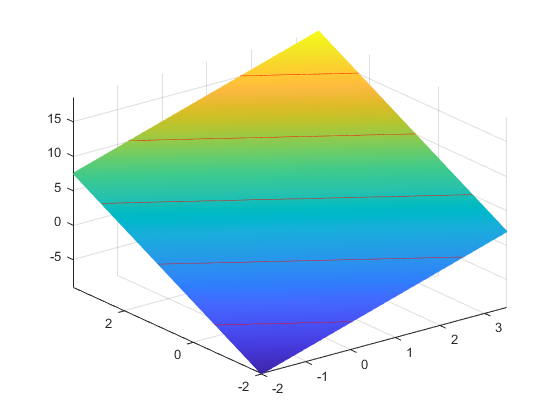




x=-2:0.01:3.5;
y=-2:0.01:3.5;

[X,Y]=meshgrid(x,y);
Z=2*X + 3*Y + 1;
figure
mesh(X,Y,Z)
hold on
contour3(X,Y,Z, 'r', 'LineWidth',1)
hold off
grid on

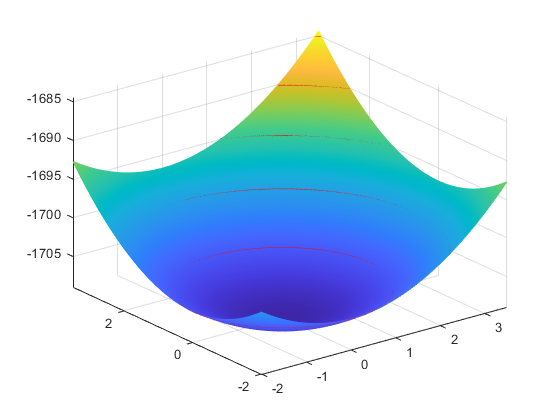


[X,Y]=meshgrid(x,y);
Z=X.^2 + Y.^2 -(X*Y) - 5;
figure
mesh(X,Y,Z)
hold on
contour3(X,Y,Z, 'r', 'LineWidth',1)
hold off
grid on

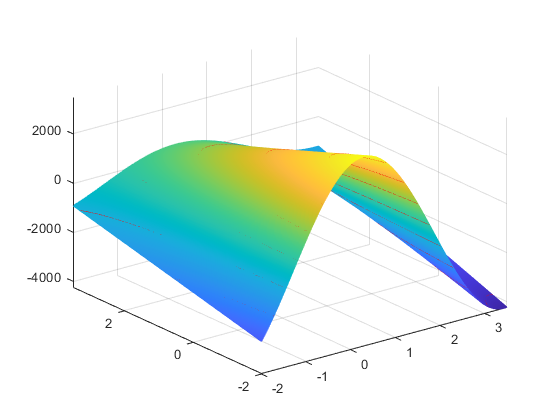


[X,Y]=meshgrid(x,y);
Z=(X-5)*cos(Y-5)-(Y-5)*sin(X-5);
figure
mesh(X,Y,Z)
hold on
contour3(X,Y,Z, 'r', 'LineWidth',1)
hold off
grid on

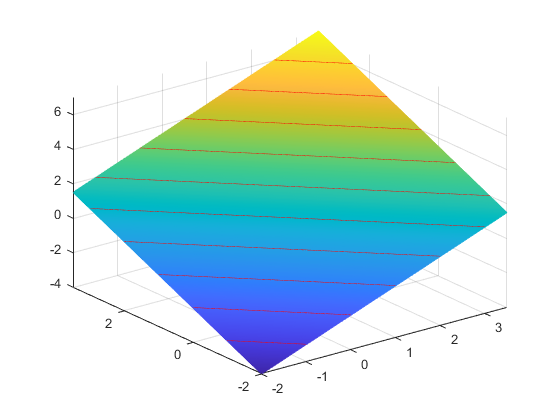


[X,Y]=meshgrid(x,y);
Z=2*X - Y + 2*Y - X;
figure
mesh(X,Y,Z)
hold on
contour3(X,Y,Z, 'r', 'LineWidth',1)
hold off
grid on

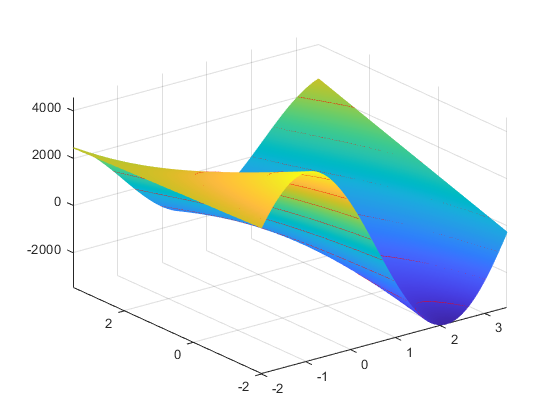


[X,Y]=meshgrid(x,y);
Z=cos(Y-5)+(5-X)*(sin(Y-5))+(5-Y)*(cos(X-5))-Y*(sin(X-5));
figure
mesh(X,Y,Z)
hold on
contour3(X,Y,Z, 'r', 'LineWidth',1)
hold off
grid on

function [time_pos, sq_wave, B_unnorm] = generate_data
    n_comps = 30; period = 10; fundFreq = 1/period;
    time_pos = 0:0.0001:2*period; harmonics = 2*(1:n_comps)-1;
    sq_wave = floor(0.9*sin(2*pi*fundFreq*time_pos))+.5; %%generate the signal
    B_unnorm = sin(2*pi*fundFreq*(harmonics'*time_pos))/2; %%generate the basis
end










